# Statistical Analysis - Part II

## Regression

General steps for building a regression model:

- Start with a hypothesis or specific goal (e.g. predicting BMI from age)

- Identify the feature you want to predict, the response variable (e.g. BMI)

- Identify the predictors - age, sex, heart rate (the input data)

- Do you expect a linear relationship?

- Visualize variables using plot functions

### Regression - Creating a Model

When creating a regression model, it is helpful to start with the simplest model (single variable) and then gradually increase the complexity. 

Simple linear regression is used for the two-variable models. With linear regression, we examine the explanatory variable and the response variable, and try to fit a linear equation to the data: $Y_1 =b*X$, where $Y_1$ is the predicited value and *b *is the regression coefficient.

Can we predict BMI from total cholesterol? There are two ways to find the slope (regression coefficient) of single-variable linear regression models*.*

1.) Use the `\` operator.

fram_noNaN.TOTCHOL \ fram_noNaN.BMI

2.) Use the `regress` function. The `regress` function removes NaN values, so we can use the original data. Before carrying out the command, assign the total cholesterol and BMI arrays to variables X and Y, respectively.

X = fram.TOTCHOL;

ans = 0.1037

Y = fram.BMI;
b = regress(Y,X)

These two methods produce the same results for *b*. In terms of predicting BMI from total cholesterol, we now have the equation $Y_1 =b*X$, where $Y_1$ is estimated BMI, *b *is the regression coefficient, and *X *is total cholesterol. Create an array containing the predicted BMI values using this equation.

Y1 = b*X;

To improve the regression model, we want to include an intercept term. In order to do this, a column of ones must be added to independent variable matrix.

X_ones = [ones(size(X)) X];

Now repeat the `regress` command with the new X variable*.*

b2 = regress(Y,X_ones)

b = 0.1038

The first term in the *b *array is the y-intercept for the linear regression line, and the second term is the slope. We now have the equation $Y_1 =b_0 *X+b_1$. Use these values to create an array which contains the new values for $Y_1$. 

Y2 = b2(2)*X_ones(:,2)+b2(1);

How do the two estimates for $Y_1$ compare? And how do these compare to that actual BMI data? Use the `scatter` function to compare. Also, calculate the $R^{2\;}$value for each relationship.

subplot(2,2,1)
scatter(X,Y1)
xlabel('Total Cholesterol')
ylabel('Predicted BMI')

b2 =    24.1091
    0.0072


title('Cholesterol vs Predicted BMI')
R_squared_1 = corr(X,Y1,"rows","complete")^2
text(200,50,['R^2 = ' num2str(R_squared_1)])

subplot(2,2,2)
scatter(Y,Y1)
xlabel('Actual BMI')
ylabel('Predicted BMI')
title('Actual vs Predicted BMI')
R_squared_2 = corr(Y,Y1,"rows","complete")^2
text(50,60,['R^2 = ' num2str(R_squared_2)])

R_squared_1 = 1


subplot(2,2,3)
scatter(X,Y2)
xlabel('Total Cholesterol')
ylabel('Predicted BMI')
title('Cholesterol vs Predicted BMI (w/ Intercept)')
R_squared_3 = corr(X,Y2,"rows","complete")^2
text(300,28,['R^2 = ' num2str(R_squared_3)])

R_squared_2 = 0.0064


subplot(2,2,4)
scatter(Y,Y2)
xlabel('Actual BMI')
ylabel('Predicted BMI')
title('Actual vs Predicted BMI (w/ Intercept)')
R_squared_4 = corr(Y,Y2,"rows","complete")^2
text(50,28,['R^2 = ' num2str(R_squared_4)])

R_squared_3 = 1

Note that when using `corr` on data of type "double", we can specify for the function to only consider complete rows. This saves us from having to remove the *NaN* values.

### Regression Model - Forecasting

We can use the regression model to predict impact in new conditions. 

Predict the BMI for a hypothetical person with a total cholesterol value of 200.

BMI_200 = b2(2)*200 + b2(1)

### Regression - Predicting New Values

Using the regression coefficient, we can examine how the predicted BMI changes with total cholesterol. For example, make an array of values from the minimum to maximum cholesterol values in increments of 10.

chol_range = min(X):10:max(X);

Create an array which contains the corresponding predicted BMI values.

Y1_predict = b2(2)*chol_range+b2(1);

Create a scatter plot with the new$\;Y_1$.

figure
scatter(chol_range,Y1_predict)
xlabel('Total Cholesterol')
ylabel('Predicted BMI')

R_squared_4 = 0.0064

We can also insert a best fit line on the original data set using the `lsline` function.

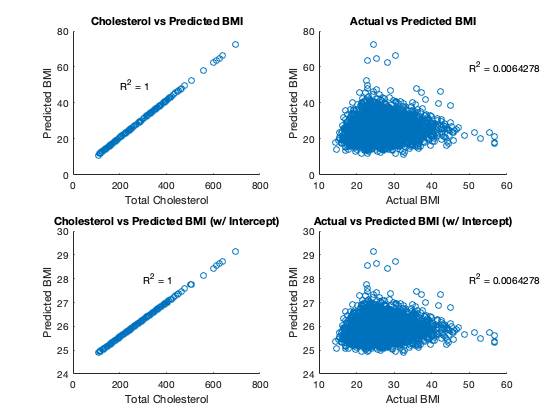

scatter(X,Y)

xlabel('Total Cholesterol')
ylabel('BMI')
h = lsline;
h.Color = 'r';

Another method for performing linear regression uses the `fitlm `command. The `fitlm` command outputs a linear regression model when given the predicting variable and the response variable.

fitlm(X,Y)

BMI_200 = 25.5538

The intercept and regression coefficient terms from the `fitlm `function give us the same equation for the best fit line as when we used the `regress` function: $Y_{1\;} =0\ldotp 0072X+24\ldotp 1\ldotp$

### Regression - Systolic and Diastolic BP

Create a linear model which uses systolic blood pressure to predict diastolic blood pressure. Plot the data points, the best fit line and find the linear regression equation.

scatter(fram.SYSBP,fram.DIABP)
xlabel('Systolic BP')
ylabel('Diastolic BP')
h = lsline;
h.Color = 'r';

fitlm(fram.SYSBP,fram.DIABP)

The equation for the best fit line is $\mathrm{DIABP}=0\ldotp 364*\mathrm{SYSBP}+33\ldotp 421\ldotp \;$The positive slope indicates that diastolic blood pressure increases with systolic blood pressure. The $r^2$ value of 0.506 indicates that there is a fairly strong linear relationship between the two variables.

## Multi-linear Regression

Most diseases and biomedical processes involve multiple parameters. In these instances, several variables may be needed to accurately predict the response variable. 

For example, BMI may be a function of age, sex, glucose, cholesterol and heart rate. The `regress `function can still be used for multi-linear regression models. To create a linear regression model with these variables, we will make a matrix containing all of the predictors plus the column of ones.

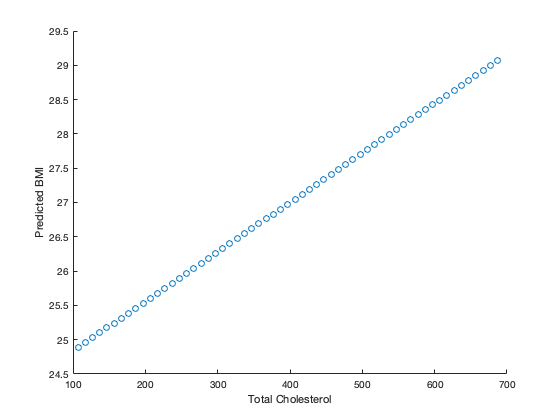

X_multi = [ones(size(fram.AGE)), fram.AGE, fram.SEX, fram.TOTCHOL, fram.GLUCOSE,...
fram.HEARTRTE];
Y_multi = fram.BMI;

b_multi = regress(Y_multi,X_multi)

What do the outputs of the `regress` function tell us about our model? These values are the regression weights and correspond to the effect of each independent variable on the dependent variable. 

Most of the features have positive correlations with BMI. We expect for BMI to increase with age, total cholesterol, glucose levels and heart rate. However, our model indicates that BMI decreases with the value for sex (1 for males, 2 for females). This suggests that on average, males have higher BMI than females.

### Multi-linear Regression - Assess Accuracy

To obtain more information about the linear regression model when using the `regress` command, use the *stats* option. This option provides the $r^2$ statistic, *F*-statistic, *p*-value, and estimated error variance.

Find the $r^2$ value for the single-variable and multi-variable regression models that we made for predicting BMI from total cholesterol.

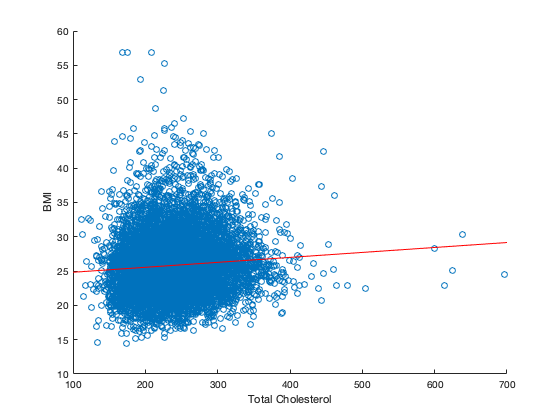

[b,~,~,~,stats] = regress(Y,X_ones);
b
stats(1)
[b_multi,~,~,~,stats_multi] = regress(Y_multi,X_multi);
b_multi

stats_multi(1)

The $r^2$ value increased from 0.0064 to 0.0235 from the single-variable model to the multi-variable model. 

While both values are very low, it makes sense that the $r^2$ value for the multi-variable linear regression is higher as we have more predicting factors for the BMI.

## Logistic Regression 

Logistic regression is used for discrete categorical data (in contrast to continuous data for linear regression).

Example – Classifying patients with diabetes versus those without diabetics.

Similar to the `regress` and `fitlm `functions, we can use the `mnrfit` function to predict diabetes from multiple variables. The `mnrfit` command returns a matrix of coefficient estimates for a multinomial logistic regression of the response variable based on the predictor variables.

Note that the response variable must be discrete, but the predictors can be continuous. We will start with just one predictor, blood glucose levels.

First, the diabetes data set must be converted to a categorical array.

diabetes = categorical(fram.DIABETES);

ans = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate         SE        tStat       pValue  
                   _________    __________    ______    __________

    (Intercept)       24.109       0.20852    115.62             0
    x1             0.0072236    0.00084972    8.5012    2.1157e-17


Number of observations: 11173, Error degrees of freedom: 11171
Root Mean Squared Error: 4.07
R-squared: 0.00643,  Adjusted R-Squared: 0.00634
F-statistic vs. constant model: 72.3, p-value = 2.12e-17

The first category is *non-diabetic*, represented by 0's. The second and last category is *diabetic*, represented by 1's. The `mnrfit` function will always use the last category as the "reference" category. The model that is returned by the function indicates the risk of being non-diabetic versus diabetic. This is especially important to remember when there are more than two categories in the response variable. 

Now that we have the categorical response variable, we can use `mnrfit` to create the model.

[B1,~,stats] = mnrfit(fram.GLUCOSE, diabetes);
B1

The first value in B1 contains the intercept term for the relative risk model. The second row contains the slope corresponding to glucose levels. This model for relative risk can be represented by the following equation:


$$\mathrm{ln}\left(\frac{\pi_{\mathrm{non}-\mathrm{diabetic}} }{\pi_{\mathrm{diabetic}} }\right)=8\ldotp 5446-0\ldotp 0565X_1$$


The model coefficients provide information about the relative risk of being in one category versus another. In this example, the coefficient -0.0565 indicates that the relative risk of being non-diabetic versus diabetic decreases exp(0.0565) for every each unit increase in glucose, if all else is equal.

Now include glucose, BMI and total cholesterol in the predictor data set.

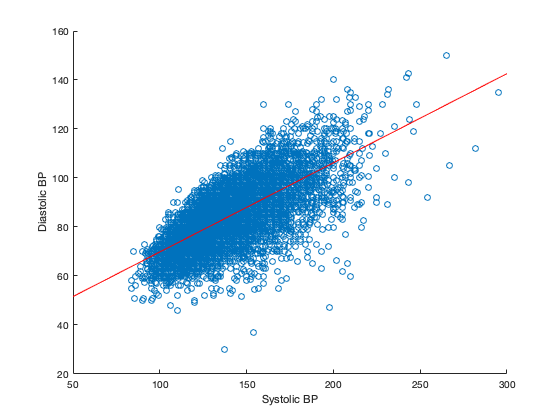

predictors = [fram.GLUCOSE, fram.BMI, fram.TOTCHOL];
[B1,~,stats] = mnrfit(predictors,diabetes);
B1

This model for relative risk can be represented by the following equation:


$$\mathrm{ln}\left(\frac{\pi_{\mathrm{non}-\mathrm{diabetic}} }{\pi_{\mathrm{diabetic}} }\right)=10\ldotp 6017-0\ldotp 0567X_1 -0\ldotp 067X_2 -0\ldotp 009X_3$$


where $X_1$is glucose, $X_2$ is BMI, and $X_3$ is total cholesterol.

We can also check if each model coefficient is statistically significant.

stats.p

ans = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE        tStat     pValue
                   ________    _________    ______    ______

    (Intercept)     33.421       0.46061    72.558      0   
    x1             0.36396     0.0033325    109.22      0   


Number of observations: 11627, Error degrees of freedom: 11625
Root Mean Squared Error: 8.19
R-squared: 0.506,  Adjusted R-Squared: 0.506
F-statistic vs. constant model: 1.19e+04, p-value = 0

We typically look for a p-value below 0.05 for determining whether the hypothesis is significant or not. The last p-value, which corresponds to total cholesterol, is much greater than 0.05, indicating that this coefficient is not significant to the model. 

### Logistic Regression - Forecasting for New data sets

We can use the `mnrval` function to evaluate the response variable (i.e. Diabetes) for new values of the predictor variables. The inputs for `mnrval` include the coefficient estimates we created with the `mnrfit `function and the values for the predictor variables that we want to analyze. The output of the function indicates the probability of belonging to each response category (Diabetic vs Non-Diabetic). 

Example: Predict if a person with Glucose =90, BMI = 24, and Cholesterol = 200 has diabetes.

x = [90 24 200];
mnrval(B1,x)

Based on these results, a person with these BMI, cholesterol and glucose levels has a 2.4% chance of having diabetes. Keep in mind that only 530 of the 11627 patients in the data set (4.56%) are diabetic. 

Repeat the prediction for a person with the following characteristics: Glucose = 160, BMI = 29, Cholesterol = 200.

x = [160 29 200];
mnrval(B1,x)

b_multi =    22.3565
    0.0148
   -0.7409
    0.0074
    0.0113
    0.0141


As expected, this patient has higher BMI and glucose levels and therefore is much more likely (64.5%) to have diabetes.

Use the same method to predict whether a patient suffered a stroke during the study (1) or not (0) based on their age, systolic blood pressure and cigarettes smoked per day. We will look at two different patients with the following characteristics: 

- **Patient 1:** Age = 50, Systolic Blood Pressure = 140, Cigarettes Smoked per Day = 6

- **Patient 2:** Age = 30, Systolic Blood Pressure = 115, Cigarettes Smoked per Day = 0

stroke = categorical(fram.STROKE);
predictors = [fram.AGE,fram.SYSBP,fram.CIGPDAY];

b =    24.1091
    0.0072


[B2,~,stats] = mnrfit(predictors,stroke);

ans = 0.0064

B2

x1 = [50,140,6];

b_multi =    22.3565
    0.0148
   -0.7409
    0.0074
    0.0113
    0.0141


prob_stroke_1 = mnrval(B2,x1)

ans = 0.0235

x2 = [30,115,0];
prob_stroke_2 = mnrval(B2,x2)

As we might expect, Patient 2 has a lower probability (1.17%) of having suffered a stroke compared to Patient 1 (5.89%) due to their lower age, blood pressure and cigarette-use.

### Polynomial Regression

The `polyfit `function is similar to `regress`, however it is more general in that `polyfit `can be used for linear, quadratic or polynomial models. The function returns the coefficients in descending powers and their length is *n+1. *

Create a first order model for systolic and diastolic blood pressure.

p = polyfit(fram.SYSBP,fram.DIABP,1)

These coefficients represent the following best fit equation: $p\left(x\right)=0\ldotp 364x+33\ldotp 42$

We can use the `polyval` function to plot the calculate the polynomial's value, *p*, at each point, *x*. Plot the original blood pressure data and the first-order best fit line on the same graph.

x1 = linspace(0,max(fram.SYSBP));
y1 = polyval(p,x1);

B1 =     8.5446
   -0.0565


figure
scatter(fram.SYSBP,fram.DIABP)
xlabel('Systolic BP')
ylabel('Diastolic BP')
hold on
plot(x1,y1)
hold on

Use `polyfit` once again, this time to create a quadratic model of the systolic and diastolic blood pressure relationship.

p2 = polyfit(fram.SYSBP,fram.DIABP,2)

B1 =    10.6017
   -0.0567
   -0.0670
   -0.0009


These coefficients form the following quadratic equation: $p\left(x\right)=-0\ldotp 0013x^{2\;} +0\ldotp 7439x+6\ldotp 305$

Add this best fit line to the previous plot.

y2 = polyval(p2,0:500);

ans =     0.0000
    0.0000
    0.0000
    0.4599


ans =     0.9760    0.0240


ans =     0.3551    0.6449


B2 =     8.3484
   -0.0548
   -0.0197
   -0.0125


prob_stroke_1 =     0.9411    0.0589


prob_stroke_2 =     0.9883    0.0117


p =     0.3640   33.4209


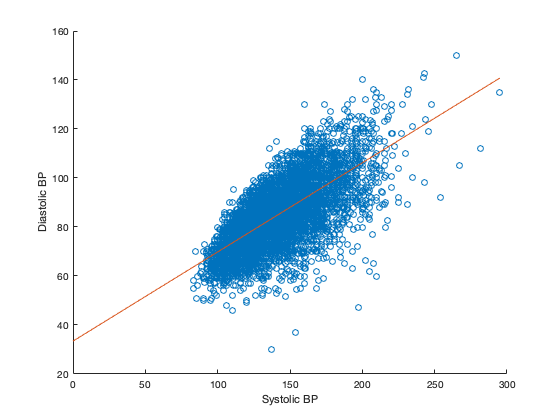

p2 =    -0.0013    0.7439    6.3051


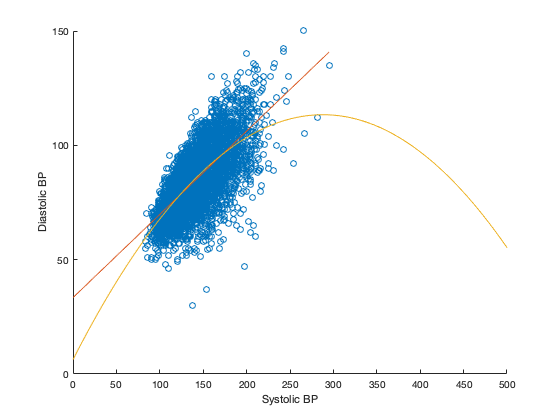

plot(0:500,y2)
hold off

In regression analysis, it is important to keep the order of the model as low as possible. In this example, it appears that the first-order model actually fits the data better. The use of polynomials of higher orders can lead to incorrect evaluations. 